# 1. AN INTRODUCTION TO SIGNALS

## 1.1 Basic Signals


% Close figures and clear memory
close all;clear;
% Definition of n axis (discrete time)
n=-10:10;

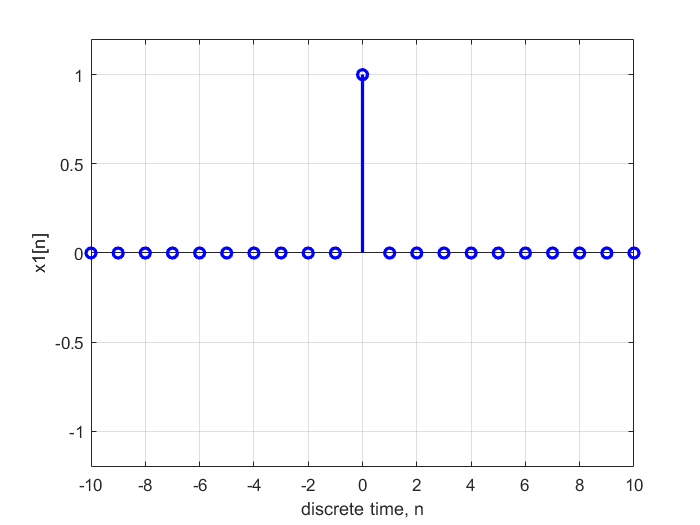

% Discrete delta function
x1=delta(n);	
figure;stem(n,x1,'b','linewidth',2);xlabel('discrete time, n'); ylabel('x1[n]');axis([-10 10 -1.2 1.2]);grid

#### (a) Is it possible to represent the signal x1[n] by using the unit step function (i.e. the signal escalon)? Change the code in the script and include a new figure that illustrates this possibility, and check your response with the graphical representation.

Yes, it is possible. We can sustract an offsetted step to the original one

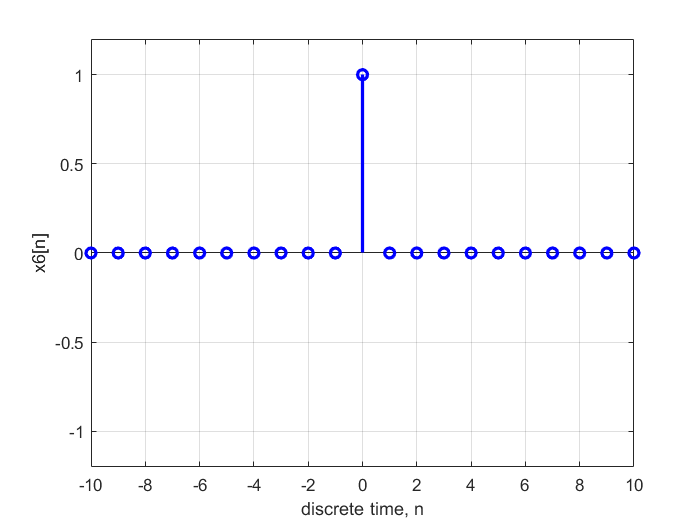

x6=escalon(n)-escalon(n-1);
figure;stem(n,x6,'b','linewidth',2);xlabel('discrete time, n'); ylabel('x6[n]');axis([-10 10 -1.2 1.2]);grid

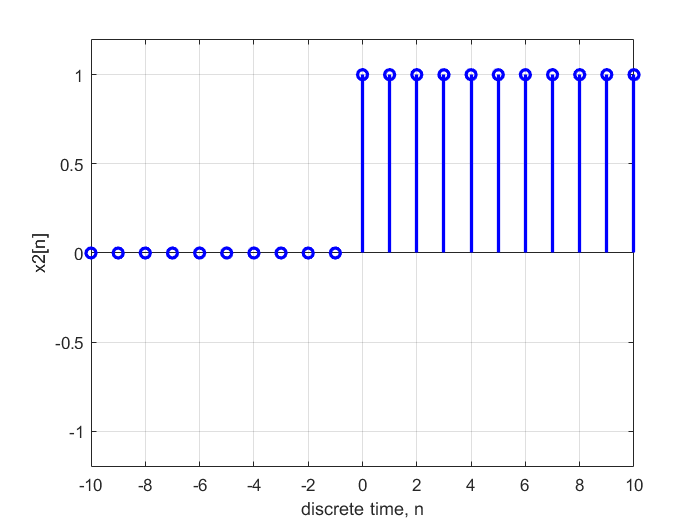

% Unit step function u(n)
x2=escalon(n);	
figure;stem(n,x2,'b','linewidth',2);xlabel('discrete time, n'); ylabel('x2[n]');axis([-10 10 -1.2 1.2]);grid

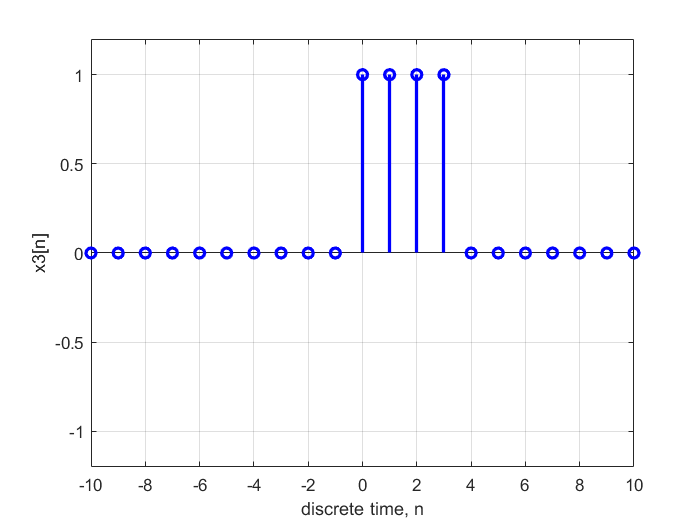

% Pulse function of width "w" samples (w>0)
w=4;
x3=pulsow(n,w);	
figure;stem(n,x3,'b','linewidth',2);xlabel('discrete time, n'); ylabel('x3[n]'); axis([-10 10 -1.2 1.2]);grid

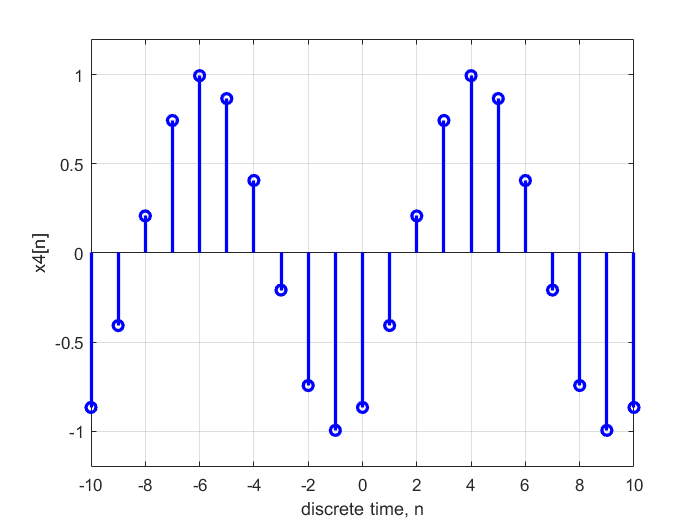

% Time-discrete sinusoid
x4=sin(pi*n/5-pi/3);	
figure;stem(n,x4,'b','linewidth',2);xlabel('discrete time, n'); ylabel('x4[n]'); axis([-10 10 -1.2 1.2]);grid

#### (b) From the code, determine the values of the angular frequency ω0 and the period N0 for the discrete-time signal x4[n]. Check that these values coincide with those deduced from the figure plot.


$$\omega_0 =\frac{\pi }{5},\omega_0 \cdot N_0 =2k\pi \to \mathrm{Let}\;k=1\to N_0 =\frac{2\pi }{\omega_0 }=\frac{2\pi \cdot 5}{\pi }=10$$


We can see that every $10\cdot n$, the values of the function repeat (note $x_4 \left\lbrack -6\right\rbrack =x_4 \left\lbrack 4\right\rbrack =1\to 4-\left(-6\right)=10,\mathrm{qed}$)

#### (c) Change the code of the script and include a new plot for the signal xS[n] = sin(n/2 − π/3). Is this signal periodic? Confirm your guess with the observation of the figure plot. 

xS=sin(n/2-pi/3);	
figure;stem(n,x4,'b','linewidth',2);xlabel('discrete time, n'); ylabel('x4[n]'); axis([-10 10 -1.2 1.2]);grid

It's aperiodic because $w_0 {\cdot N}_0 \not\equiv 2\pi \;\forall N\in Z\to N_0 =2\pi \cdot 2=4\pi \not\in Z,\mathrm{qed}$

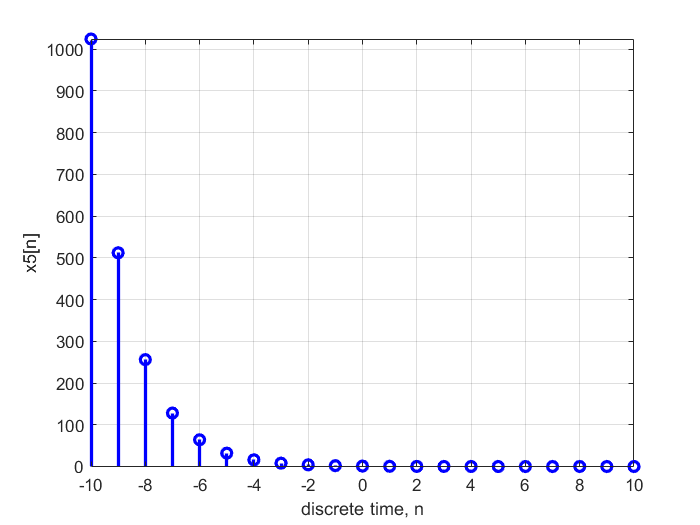

% Exponential signal
a=1/2;
x5=a.^n;	
figure;stem(n,x5,'b','linewidth',2);xlabel('discrete time, n'); ylabel('x5[n]'); axis([-10 10 -1.2 2^10]);grid

#### (d) Change the code of the script so that the signal x5[n] is nulled for n < 0, and represent the result in a new figure. What’s the mathematical expression for the new signal? 

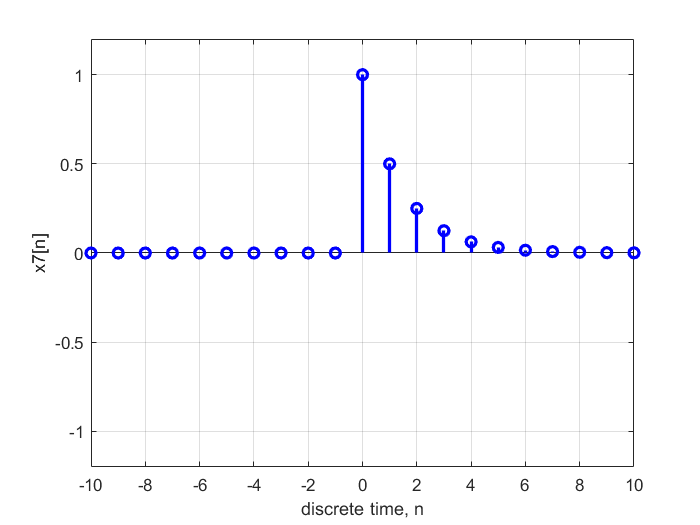

x7=a.^n .*escalon(n);	
figure;stem(n,x7,'b','linewidth',2);xlabel('discrete time, n'); ylabel('x7[n]'); axis([-10 10 -1.2 1.2]);grid


$$x_7 \left\lbrack n\right\rbrack =a^n \cdot u\left\lbrack n\right\rbrack$$


## 1.2 Amplitude scaling and shifting

% Close figures and clear memory
close all;clear;
% Definition of n axis (discrete time)
n=-10:10;

#### Starting from the previous script, create a new one named ShiftScaleAmp in which the following set of signals (built from amplitude scaling and shifting over the basic set of signals previously introduced) are represented:

#### 
$$\begin{array}{l}
e_1 \left\lbrack n\right\rbrack =-\mathrm{escalon}\left\lbrack n\right\rbrack \\
e_2 \left\lbrack n\right\rbrack =2\cdot \mathrm{escalon}\left\lbrack n\right\rbrack -1\\
p_1 \left\lbrack n\right\rbrack =-2\cdot \mathrm{pulsow}\left\lbrack n,3\right\rbrack +1\\
p_2 \left\lbrack n\right\rbrack =2\cdot \mathrm{delta}\left\lbrack n\right\rbrack -2
\end{array}$$


#### (a) Run the script ShiftScaleAmp and verify that the figure plots correspond with the expected results. 

e1=(-1).*escalon(n);
figure;stem(n,e1,'b','linewidth',2);xlabel('discrete time, n'); ylabel('e1[n]'); axis([-10 10 -1.2 1.2]);grid
% 
e2=2.*escalon(n)-1;
figure;stem(n,e2,'b','linewidth',2);xlabel('discrete time, n'); ylabel('e2[n]'); axis([-10 10 -1.2 1.2]);grid
%
p1=(-2).*pulsow(n,3);
figure;stem(n,p1,'b','linewidth',2);xlabel('discrete time, n'); ylabel('p1[n]'); axis([-10 10 -2 2]);grid
%
p2=(2).*delta(n)-2;
figure;stem(n,p2,'b','linewidth',2);xlabel('discrete time, n'); ylabel('p2[n]'); axis([-10 10 -2 2]);grid

#### (b) Fill the blanks in the script ap12 included below, so that the resulting signals coincide with those in Figure 1 (see next page). For this purpose, use only the following set of signals: delta, unit step, pulse, sine and constant values, without resorting to discrete-time shifting.

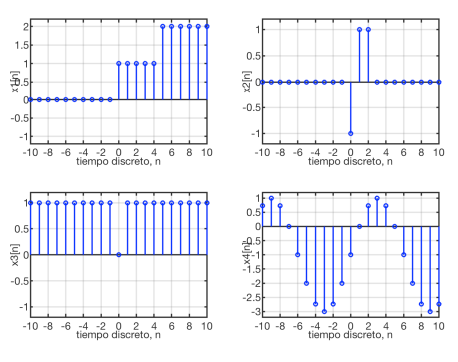

#### (c) Build the script ap12, run it, and verify that the figure plots coincide with the expected outcome. 

%ap12 Figure plots for time-discrete signals
% Close figures and clear memory
close all;clear ;
% Definition of n axis (discrete time)
n=-10:10;
% Combination of unit step and pulse signals
x1=escalon(n)+escalon(n-5);
subplot(221);stem(n,x1,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' x1[n] ');axis([-10 10 -1.2 2.2]);grid
% Combination of pulse and delta signals
x2=pulsow(n,3)-2.*delta(n);
subplot(222);stem(n,x2,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' x2[n] ');axis([-10 10 -1.2 1.2]);grid
% Combination of basic signals and constant values
x3=1-delta(n);
subplot(223);stem(n,x3,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' x3[n] ');axis([-10 10 -1.2 1.2]);grid
% Combination of time disecrete sinusoid and constant amplitude shift
A=2;
B=-1;
x4=A*sin(pi*n/6)+B;
subplot(224);stem(n,x4,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' x4[n]');axis([-10 10 -3.2 1.2]);grid

## 1.3 Discrete Time Scaling and Shifting

#### Starting from the previous scripts, build a new one named ShiftScaleAxis on which the following set of signals (corresponding to time scaling and shifting over the set of basic signals) is represented: 

#### 
$$\begin{array}{l}
d_1 \left\lbrack n\right\rbrack =\mathrm{delta}\left\lbrack n+2\right\rbrack \\
d_2 \left\lbrack n\right\rbrack =\mathrm{delta}\left\lbrack n-2\right\rbrack 
\end{array}$$


#### 
$$\begin{array}{l}
e_1 \left\lbrack n\right\rbrack =\mathrm{escalon}\left\lbrack -n-1\right\rbrack \\
e_2 \left\lbrack n\right\rbrack =\mathrm{escalon}\left\lbrack -\left(n-1\right)\right\rbrack \\
p_1 \left\lbrack n\right\rbrack =\mathrm{pulsow}\left\lbrack 2n+3,8\right\rbrack \\
p_2 \left\lbrack n\right\rbrack =\mathrm{pulsow}\left\lbrack -2\left(n+1\right),6\right\rbrack 
\end{array}$$


#### (a) Run the script ShiftScaleAxis and verify that the figure plots coincide with the expected outcome from theory.

d1= delta(n+2);
figure;stem(n,d1,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' d1[n] ');axis([-10 10 -1.2 2.2]);grid
d2= delta(n-2);
figure;stem(n,d2,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' d2[n] ');axis([-10 10 -1.2 2.2]);grid
e1= escalon(-n-1);
figure;stem(n,e1,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' e1[n] ');axis([-10 10 -1.2 2.2]);grid
e2= escalon(-(n-1));
figure;stem(n,e2,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' e2[n] ');axis([-10 10 -1.2 2.2]);grid
p1= pulsow(2*n + 3, 8);
figure;stem(n,p1,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' p1[n] ');axis([-10 10 -1.2 2.2]);grid
p2= pulsow(-2*(n + 1), 6);
figure;stem(n,p2,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' p2[n] ');axis([-10 10 -1.2 2.2]);grid

#### (b) Fill the blanks in the script ap13 included below, so that the resulting signals coincide with those in Figure 2 (see next page). For this purpose, use only combinations of the basic signals (delta, unit step, pulse, sine and constant values), with any amplitude value and conveniently shifted/scaled. 

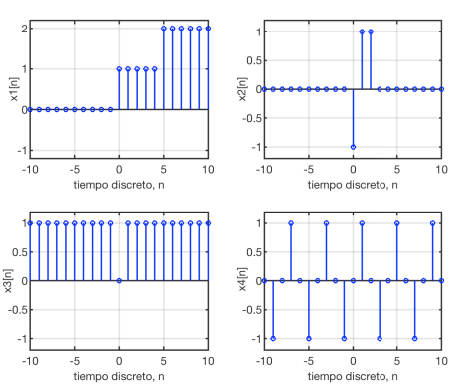

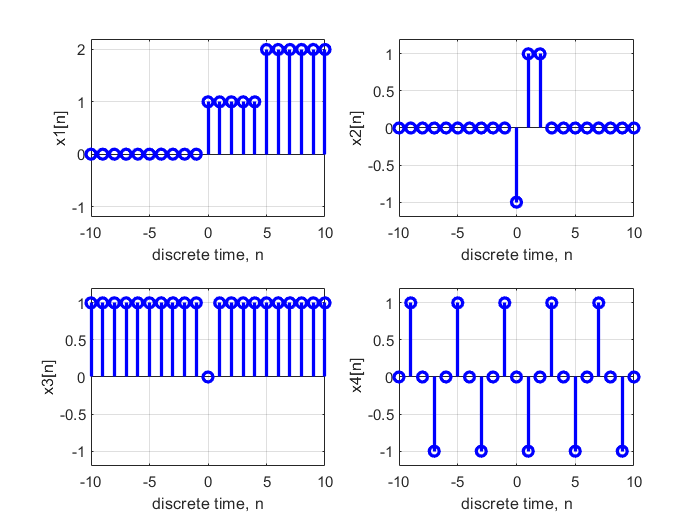

%ap13 Figure plots for time-discrete signals
% Close figures and clear memory
close all;clear ;
% Definition of n axis (discrete time)
n=-10:10;
% Combination of pulse signals using time shifting
x1=pulsow(n,11)+pulsow(n-5,6);
 subplot(221);stem(n,x1,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' x1[n] ');axis([-10 10 -1.2 2.2]);grid
% Combination of delta signals using time shifting
x2=-delta(n)+delta(n-1)+delta(n-2);
subplot(222);stem(n,x2,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' x2[n] ');axis([-10 10 -1.2 1.2]);grid
% Combination of unit step functions using time scaling and shifting
x3=escalon(-n-1)+escalon(n-1);
subplot(223);stem(n,x3,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' x3[n] ');axis([-10 10 -1.2 1.2]);grid
% Combination of a discrete time sinusoid and time scaling/shifting
A=1;
B=pi;
x4=A*sin(pi*n/2+B);
subplot(224);stem(n,x4,'b','linewidth',2);xlabel('discrete time, n'); ylabel(' x4[n]');axis([-10 10 -1.2 1.2]);grid

# 2. AN INTRODUCTION TO SYSTEMS

## 2.1 Time invariance

####  List 4 examines the response of the system system1 to different input signals, as indicated in Figure 3. Run the script Invariance.m and answer the following questions: 

% Time invariance. Response of system1 to two different inputs

% Close figures and clear memory
close all;clear;
% Definition of n axis (discrete time)
n=-10:10;

figure;
% Input signal
x1=delta(n)+delta(n-1)+delta(n-2);
subplot(221);	% upper subfigure in figure 1
stem(n,x1,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' x1[n] ');
axis([-10 10 -1.5 1.5]);grid
% Output signal
y1=system1(x1);
subplot(222);	% lower subfigure in figure 1
stem(n,y1,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y1[n] ');
axis([-10 10 -0.5 25]);grid

% Input signal (shifted by 5 samples)
x2=delta(n-5)+delta(n-6)+delta(n-7);
subplot(223);	% upper subfigure in figure 2
stem(n,x2,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' x2[n] ');
axis([-10 10 -1.5 1.5]);grid
% System response to shifted input
y2=system1(x2);
subplot(224);	% lower subfigure in figure 2
stem(n,y2,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y2[n] ');
axis([-10 10 -0.5 25]);grid

#### (a) After the inspection of the figure plots: what can we say about the time invariance of system1 ? 


$$y\left\lbrack n-n_0 \right\rbrack =T\left\lbrace x\left\lbrack n-n_0 \right\rbrack \right\rbrace$$
 

It is not time invariant, because it's shifted but it doesn't have the same amplitude. 

#### (b) Modify the previous script in order to run the same test over the system system2. Run this new script Invariance2.m: what can we now say about the time invariance of system2 ? 

####     Note: In the code, change the axis parameters to (-10,10,-1.5,1.5) for the case of using subplot(212).

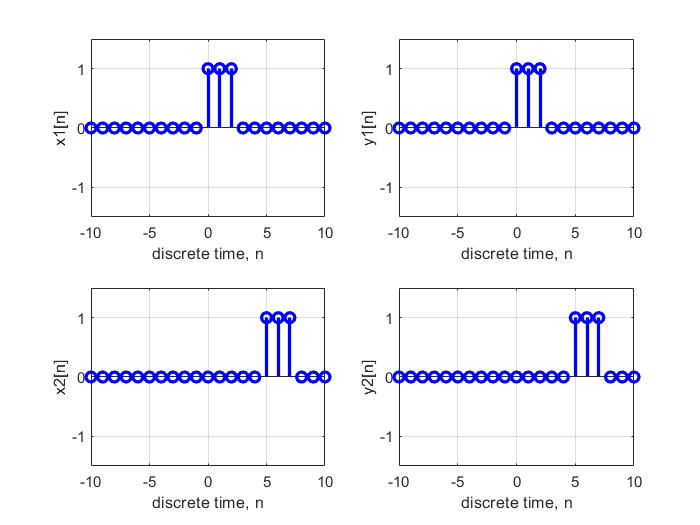

% Time invariance. Response of system1 to two different inputs

% Close figures and clear memory
close all;clear;
% Definition of n axis (discrete time)
n=-10:10;

figure;
% Input signal
x1=delta(n)+delta(n-1)+delta(n-2);
subplot(221);	% upper subfigure in figure 1
stem(n,x1,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' x1[n] ');
axis([-10 10 -1.5 1.5]);grid
% Output signal
y1=system2(x1);
subplot(222);	% lower subfigure in figure 1
stem(n,y1,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y1[n] ');
axis([-10 10 -1.5 1.5]);grid

% Input signal (shifted by 5 samples)
x2=delta(n-5)+delta(n-6)+delta(n-7);
subplot(223);	% upper subfigure in figure 2
stem(n,x2,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' x2[n] ');
axis([-10 10 -1.5 1.5]);grid
% System response to shifted input
y2=system2(x2);
subplot(224);	% lower subfigure in figure 2
stem(n,y2,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y2[n] ');
axis([-10 10 -1.5 1.5]);grid

## 2.2 Linearity

#### List 5 examines the response of system1 to different input signals, as indicated in Figure 4. 

#### (a) Run the script Linearity.m. After the inspection of the figure plots, what can we say about the linearity of system1 ? 

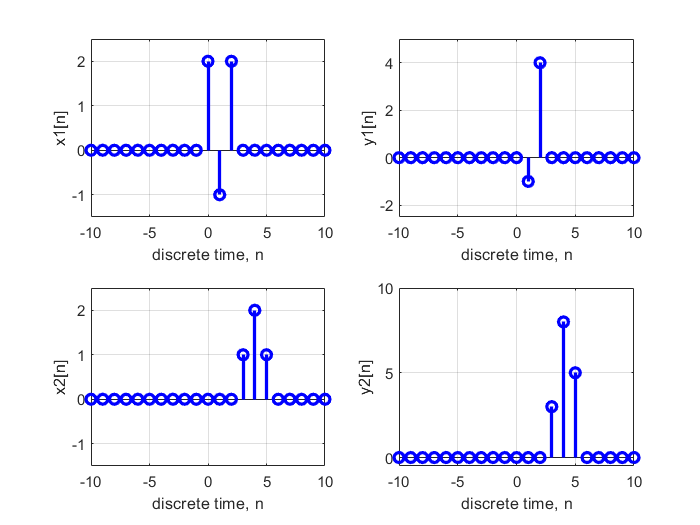

% Linearity.
% Close figures and clear memory
close all;clear;
% Definition of n axis (discrete time)
n=-10:10;

figure;
% Input signal x1
x1=2*delta(n)-delta(n-1)+2*delta(n-2);
subplot(221);	% upper subfigure in figure 1
stem(n,x1,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' x1[n] ');
axis([-10 10 -1.5 2.5]);grid
% Output signal y1
y1=system1(x1);
subplot(222);	% lower subfigure in figure 1
stem(n,y1,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y1[n] ');
axis([-10 10 -2.5 5]);grid
% Input signal x2
x2=delta(n-3)+2*delta(n-4)+delta(n-5);
subplot(223);	% upper subfigure in figure 2
stem(n,x2,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' x2[n] ');
axis([-10 10 -1.5 2.5]);grid
% Output signal y2
y2=system1(x2);
subplot(224);	% lower subfigure in figure 2
stem(n,y2,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y2[n] ');
axis([-10 10 -0.5 10]);grid

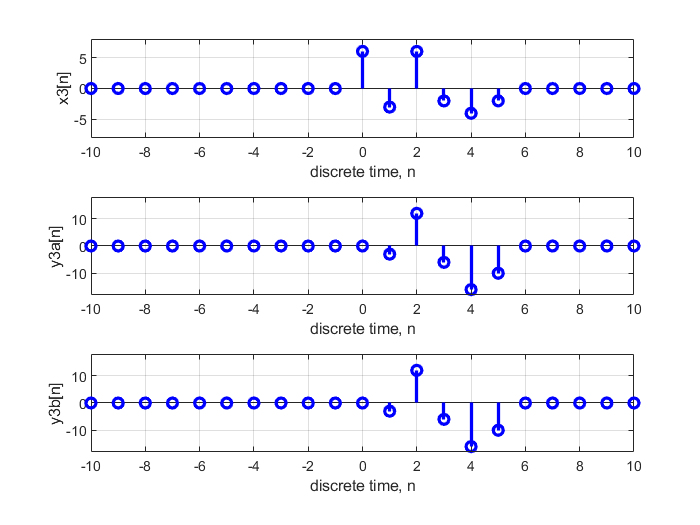

% Input signal x3 = Linear combination of x1 and x2
figure;
x3=3*x1-2*x2;
subplot(311);	% upper subfigure in figure 3
stem(n,x3,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' x3[n] ');
axis([-10 10 -8 8]);grid
% Output signal y3
y3a=system1(x3);
subplot(312);	% middle subfigure in figure 3
stem(n,y3a,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y3a[n] ');
axis([-10 10 -18 18]);grid
% Combination of y1 and y2
y3b=3*y1-2*y2;
subplot(313);	% lower subfigure in figure 3
stem(n,y3b,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y3b[n] ');
axis([-10 10 -18 18]);grid

It is linear, since $y_{3a} =T\left\lbrace {3x}_1 \left\lbrack n\right\rbrack -2x_2 \left\lbrack n\right\rbrack \right\rbrace \;\mathrm{and}\;y_{3b} =3y_1 \left\lbrack n\right\rbrack -2y_2 \left\lbrack n\right\rbrack$are equal. 

#### (b) Modify the previous script in order to run the same test over the system system2. Run this new script Invariance2.m: what can we now say about the linearity of system2 ? 

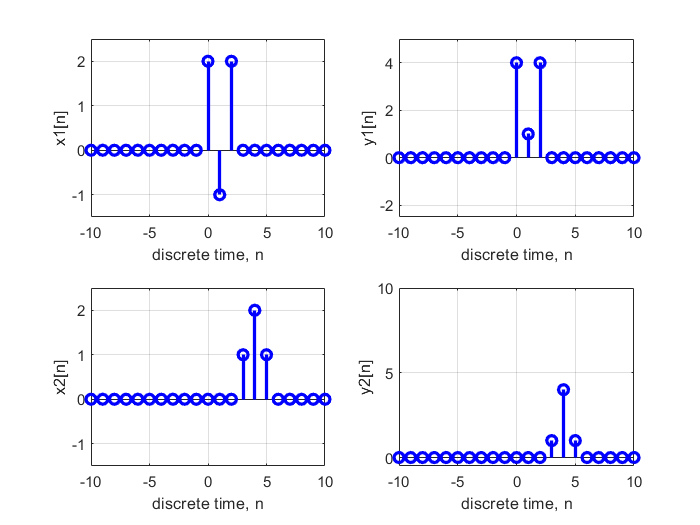

% Linearity.
% Close figures and clear memory
close all;clear;
% Definition of n axis (discrete time)
n=-10:10;

figure;
% Input signal x1
x1=2*delta(n)-delta(n-1)+2*delta(n-2);
subplot(221);	% upper subfigure in figure 1
stem(n,x1,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' x1[n] ');
axis([-10 10 -1.5 2.5]);grid
% Output signal y1
y1=system2(x1);
subplot(222);	% lower subfigure in figure 1
stem(n,y1,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y1[n] ');
axis([-10 10 -2.5 5]);grid
% Input signal x2
x2=delta(n-3)+2*delta(n-4)+delta(n-5);
subplot(223);	% upper subfigure in figure 2
stem(n,x2,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' x2[n] ');
axis([-10 10 -1.5 2.5]);grid
% Output signal y2
y2=system2(x2);
subplot(224);	% lower subfigure in figure 2
stem(n,y2,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y2[n] ');
axis([-10 10 -0.5 10]);grid

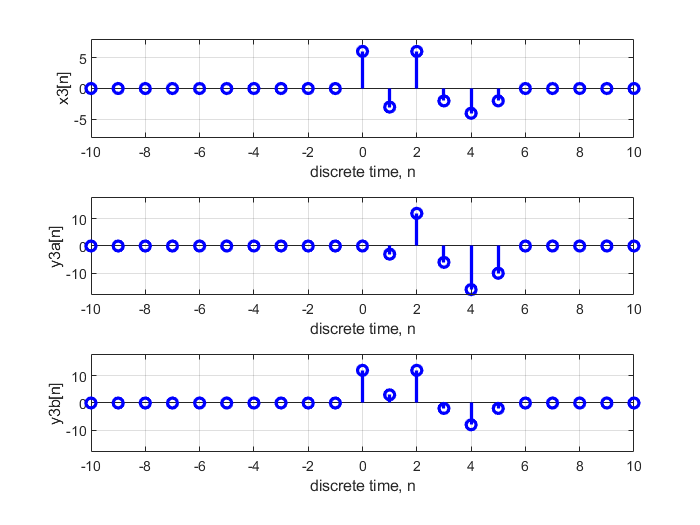

% Input signal x3 = Linear combination of x1 and x2
figure;
x3=3*x1-2*x2;
subplot(311);	% upper subfigure in figure 3
stem(n,x3,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' x3[n] ');
axis([-10 10 -8 8]);grid
% Output signal y3
y3a=system1(x3);
subplot(312);	% middle subfigure in figure 3
stem(n,y3a,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y3a[n] ');
axis([-10 10 -18 18]);grid
% Combination of y1 and y2
y3b=3*y1-2*y2;
subplot(313);	% lower subfigure in figure 3
stem(n,y3b,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y3b[n] ');
axis([-10 10 -18 18]);grid

It isn't linear, since $y_{3a} =T\left\lbrace {3x}_1 \left\lbrack n\right\rbrack -2x_2 \left\lbrack n\right\rbrack \right\rbrace \;\textrm{and}\;y_{3b} =3y_1 \left\lbrack n\right\rbrack -2y_2 \left\lbrack n\right\rbrack$are unequal. 

## 2.3 Causality

#### List 6 examines the response of the systems system3 and system4 to the input x1[n]. 1. Run the script Causality.m.After the inspection of the figure plots, what can we say about the causality of system3 and system4 ? 

% Causality. 
% Close figures and clear memory
close all;clear;
% Definition of n axis (discrete time)
n=-10:10;

figure(1);
% Input signal x1
x1=delta(n)+2*delta(n-2);
subplot(221);	% upper subfigure in figure 1
stem(n,x1,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' x1[n] ');
axis([-10 10 -1.5 2.5]);grid
% Output signal y1
y1=system3(x1);
subplot(222);	% lower subfigure in figure 1
stem(n,y1,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y1[n] ');
axis([-10 10 -2.5 5]);grid
% Input signal x1
x1=delta(n)+2*delta(n-2);
subplot(223);	% upper subfigure in figure 2
stem(n,x1,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' x2[n] ');
axis([-10 10 -1.5 2.5]);grid
% Output signal y2
y2=system4(x1);
subplot(224);	% lower subfigure in figure 2
stem(n,y2,'b','linewidth',2); xlabel('discrete time, n'); ylabel(' y2[n] ');
axis([-10 10 -2.5 5]);grid

$y_1 \left\lbrack n\right\rbrack \;$is not causal, since ${\exists \;y}_1 \left\lbrack -1\right\rbrack =T\left\lbrace x\left\lbrack n\right\rbrack \right\rbrace \;\forall n>0$

$y_2 \left\lbrack n\right\rbrack \;$is causal, since $\mathrm{not}\left(\exists y_2 \left\lbrack n\right\rbrack \right)\forall \;n<0\;/y_2 \left\lbrack n\right\rbrack =T\left\lbrace x\left\lbrack n\right\rbrack \right\rbrace \;\forall n>0$

## 2.4 System Combination

#### List 7 examines the output of the system system5 to a given input x[n]. The system system5 is defined as the combination and interconnection of a number of simpler sub-systems, as indicated in List 8.

#### 2. Run the script Combinacion.m. What can we say about the causality of system5 ? 

% System combination

% Close figures and clear memory
close all;
Definitionn=-10:10;
figure;
x=pulsow(n,4);
y=system5(x);
subplot(211)
stem(n,x,'b','linewidth',2);  xlabel('discrete time, n'); ylabel(' x[n] ');
axis([-10 10 -1.5 1.5]);grid
subplot(212)
stem(n,y,'r','linewidth',2);  xlabel('discrete time, n'); ylabel(' y[n] ');
axis([-10 10 -4.5 4.5]);grid

We cannot say it isn't causal, because it is causal for the given input signal. 

#### 3. The system system5 is linear and time invariant. What’s the expression for its impulse response? Calculate an analytical expression from the individual impulse responses of the systems systemA, systemB and systemC. Modify the script Combinacion.m and run it, so you can verify this result from the figure plots.


$$h\left\lbrack n\right\rbrack =3\delta \left\lbrack n-3\right\rbrack *\left(\delta \left\lbrack n\right\rbrack -\delta \left\lbrack n-1\right\rbrack \right)+\delta \left\lbrack n-1\right\rbrack -2\delta \left\lbrack n-2\right\rbrack +\delta \left\lbrack n-3\right\rbrack$$



$$3\delta \left\lbrack n-3\right\rbrack *\left(\delta \left\lbrack n\right\rbrack -\delta \left\lbrack n-1\right\rbrack \right)=3\delta \left\lbrack n-3\right\rbrack -3\delta \left\lbrack n-4\right\rbrack$$



$$h\left\lbrack n\right\rbrack =\delta \left\lbrack n-1\right\rbrack -2\delta \left\lbrack n-2\right\rbrack +4\delta \left\lbrack n-3\right\rbrack -3\delta \left\lbrack n-4\right\rbrack$$


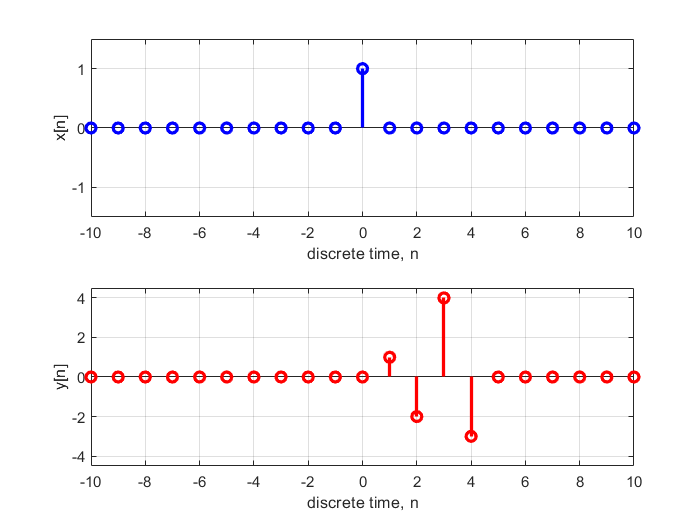

% System combination
% Close figures and clear memory
close all;
Definitionn=-10:10;
figure;
x=delta(n);
y=system5(x);
subplot(211)
stem(n,x,'b','linewidth',2);  xlabel('discrete time, n'); ylabel(' x[n] ');
axis([-10 10 -1.5 1.5]);grid
subplot(212)
stem(n,y,'r','linewidth',2);  xlabel('discrete time, n'); ylabel(' y[n] ');
axis([-10 10 -4.5 4.5]);grid